# Import Data Demo

This Live script explain how to add interactively new exergy or resource data to the model.

data=ReadDataModel('cgam_model.xlsx');

#### 1. Import Data from a CSV file

The file `ExergyData.csv `contain the exergy values of a simulaton of the CGAM plant

The file is imported into a `cTable` that contains the exergy values in the first column

tbl=ImportData('ExergyData.csv');
val=tbl.getColumnValue(1);

#### 2. Add the new data to the data model

These values are loaded into a new state called` 'Test', `with the function `addExergyData.`

Data model must be updated, function `updateModel`, if we can show and use the new state:

data.addExergyData('Test',val);
disp(data.StateNames);

    {'REF'}    {'T1180'}    {'ETG87'}    {'ECMP84'}    {'RP8'}    {'PINCH15'}    {'CGAMR'}    {'noAPH'}    {'Test'}



data.updateModel;
ShowResults(data,'Table','Exergy');


Exergy Data

 key          REF       T1180       ETG87      ECMP84         RP8     PINCH15       CGAMR       noAPH        Test 
————————————————————————————————————————————————————————————————————————————————————————————————————————————————————
 NG        72.465      73.327        73.6      73.297      72.283      72.465      72.465      97.896      75.805 
 B1             0           0           0           0           0           0           0           0           0 
 B2        28.651      29.507      29.337      29.196      27.863      28.651      28.651      25.141      28.614 
 B3        50.339      50.896      51.926      51.018      51.048      50.339      50.339      25.141      48.095 
 B4        102.53     103.462     104.971     103.813     103.163      102.53      102.53      91.046     102.461 
 B5         38.81      38.735       40.23      39.295      40.324       38.81       38.81      31.211      38.784 
 B6        14.784      15.021      15.213      15.137      14.59

res=ThermoeconomicAnalysis(data,'State','Test');
ShowResults(res,'Table','dfcost');


Flows Exergy Cost - Test

Key         B(MW)      B*(MW)    Bin*(MW)     Br*(MW)      k*(J/J)    kin*(J/J)     kr*(J/J)
—————————————————————————————————————————————————————————————————————————————————————————————
NG         75.805      75.805      75.805       0.000       1.0000       1.0000       0.0000
B1          0.000       0.000       0.000       0.000       0.0000       0.0000       0.0000
B2         28.614      53.466      51.257       2.209       1.8685       1.7913       0.0772
B3         48.095      90.066      86.324       3.743       1.8727       1.7949       0.0778
B4        102.461     168.052     162.129       5.923       1.6402       1.5823       0.0578
B5         38.784      63.612      61.370       2.242       1.6402       1.5823       0.0578
B6         16.623      27.264      26.303       0.961       1.6402       1.5823       0.0578
B7          1.731       2.839       2.739       0.100       1.6402       1.5823       0.0578
WC         31.064      53.202      51.257 

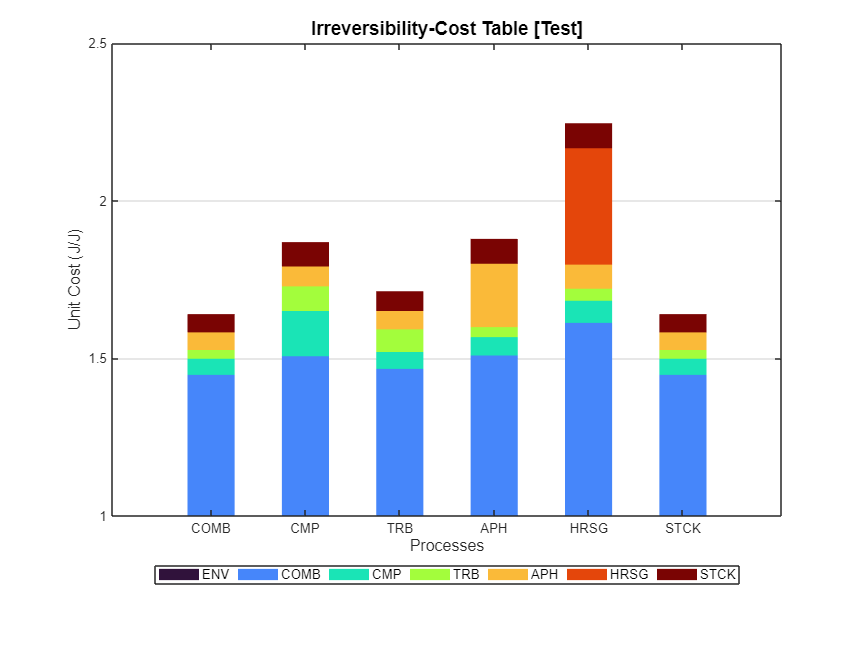

ShowGraph(res,'Graph','dict');

#### 3. Import Resource Cost data

Import the files `ResouceFlows.csv` that contains the unit cost of resource flows and `ResourceProcesses.csv `that contains the cost of processes.

tbl=ImportData('ResourceFlows.csv');
rval=tbl.getColumnData(2);
tbl=ImportData('ResourceProcesses.csv');
pval=tbl.getColumnValue(2);

Create a new resource sample `'Test' `with this data values.

data.addResourceData('Test',rval,pval);
disp(data.SampleNames);

    {'Base'}    {'CGAMR'}    {'Test'}



#### 4. Update the model and show results

data.updateModel;
ShowResults(data,'Table','ResourcesCost');


Resources Cost

 Key    Type            Base       CGAMR        Test 
———————————————————————————————————————————————————————
 NG     FLOW              30          30          35 
 B1     FLOW               0           0        0.01 
 COMB   PROCESS          3.6         3.6         3.7 
 CMP    PROCESS         32.5        32.5          34 
 TRB    PROCESS           46          46          48 
 APH    PROCESS           20          20          21 
 HRSG   PROCESS           35           0          37 
 STCK   PROCESS            0           0           0 



res=ThermoeconomicAnalysis(data,'State','Test','CostTable','ALL','ResourceSample','Test');
ShowResults(res,'Table','gfcost');


Flows Generalized Cost - [Test/Test]

Key         B(MW)       C($/h)     Cin($/h)      Cz($/h)      Cr($/h)    c($/MWh)  cin($/MWh)   cz($/MWh)   cr($/MWh)
——————————————————————————————————————————————————————————————————————————————————————————————————————————————————————
NG         75.805     2653.175     2653.175        0.000        0.000       35.00       35.00        0.00        0.00
B1          0.000        0.000        0.000        0.000        0.000        0.00        0.00        0.00        0.00
B2         28.614     1977.986     1794.007      114.620       69.359       69.13       62.70        4.01        2.42
B3         48.095     3312.208     3021.329      174.070      116.809       68.87       62.82        3.62        2.43
B4        102.461     6071.659     5674.504      177.770      219.385       59.26       55.38        1.73        2.14
B5         38.784     2298.272     2147.939       67.290       83.043       59.26       55.38        1.73        2.14
B6         16.62

#### 5. Modify Waste Definition Parameters

data.setWasteType('QG','RESOURCES');
data.updateModel;
data.showWasteDefinition;


Waste Definition

 key   type           recycle 
————————————————————————————————
 QG    RESOURCES            0 

